clc
clear all
% k = 7000; %lbs*in
b = 120; %in
c = 48;
e = 0.7 * 48  - 0.25 * 48 %in

e = 21.6000

S = c*b; %in^2
p = 14.7; %psi
gamma = 1.4; %air
M = 0.7

M = 0.7000

q = linspace(0.1,1,4)

q =     0.1000    0.4000    0.7000    1.0000


Cl_A =      [0.1697 0.1727 0.1757 0.1789]

Cl_A =     0.1697    0.1727    0.1757    0.1789


Cl_d =      [0.0149 0.0148 0.0148 0.0147]

Cl_d =     0.0149    0.0148    0.0148    0.0147


delta_0 =   [28.04 25.24 25.96 26.72]

delta_0 =    28.0400   25.2400   25.9600   26.7200


theta =     [26.09 6.54 3.74 2.61]

theta =    26.0900    6.5400    3.7400    2.6100


alpha =     [26.04 6.40 3.59 2.47]

alpha =    26.0400    6.4000    3.5900    2.4700


% q = (gamma.*p.*(M).^2)./2
% by doing a match Point analysis where q (dynamic pressure) which is written as a funciton of Altitude as 


$$q=\frac{\gamma }{2}{\textrm{pM}}^{2\;}$$


where p is the pressure (this includes the altitude information).

L_flex = q.*S.*e.*Cl_A.*(alpha + theta) + q.*e.*S.*Cl_d.*delta_0

L_flex = 	1.0e+05 *

    1.1526    1.2981    1.4562    1.6194


L_rigid = q.*S.*e.*Cl_d.*delta_0

L_rigid = 	1.0e+04 *

    0.5198    1.8590    3.3461    4.8869


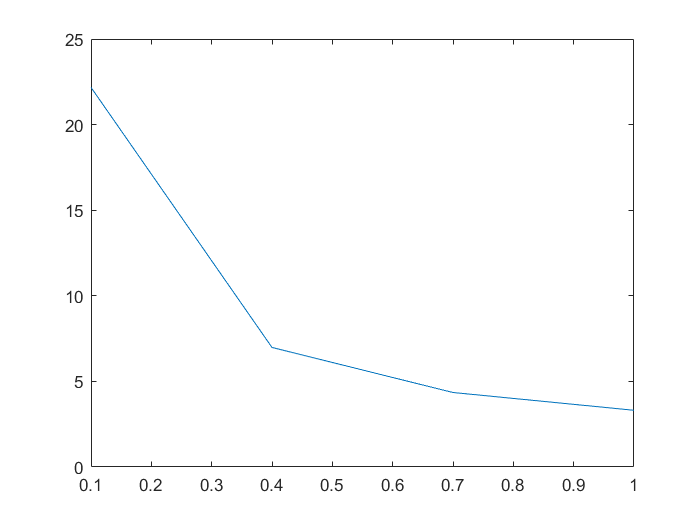

ratio = L_flex./L_rigid;
plot(q,ratio)

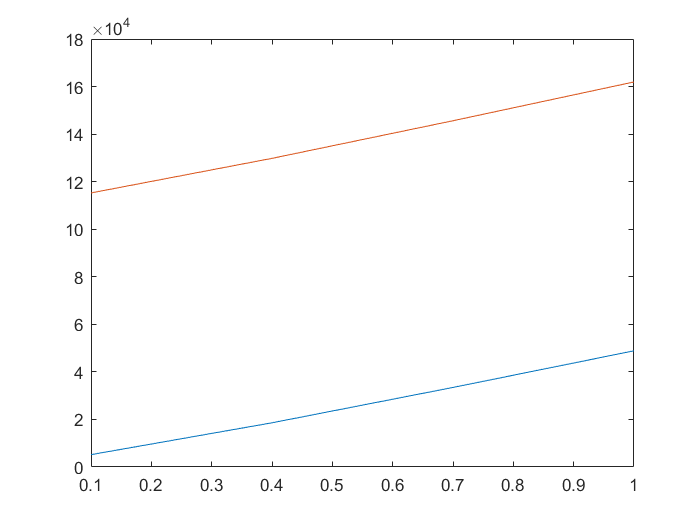

plot(q,L_rigid)
hold on
plot(q,L_flex)
hold off

% % % Sub-sonic Case
% % M_sub = linspace(0,0.8,100);
% % Cl_Sub = (2.*pi)./sqrt(1 - (M_sub.^2))
% % Qd_Sub = (0.5858 .* k .* b.^2)./(S .* e .* Cl_Sub);
% % Q_Sub = (gamma.*p.*(M_sub).^2)./2;  
% % % Super-sonic case
% % M_sup = linspace(1.2,4,100); 
% % Cl_Sup = (4)./sqrt((M_sup.^2) - 1);
% % Qd_Sup = (0.5858 .* k .* b.^2)./(S .* e .* Cl_Sup);
% % Q_Sup = (gamma.*p.*(M_sup).^2)./2;
% % % Plot
% % hold on
% % plot(M_sub,Qd_Sub,"DisplayName",'Qd_S_u_b')
% % plot(M_sub,Q_Sub,"DisplayName",'Q_S_u_b')
% % plot(M_sup,Qd_Sup,"DisplayName",'Qd_S_u_p')
% % plot(M_sup,Q_Sup,"DisplayName",'Q_S_u_p')
% % hold off
% % legend('Location','northwest')
% % xlabel('Mach Number')
% % ylabel('q')
% % title('Divergence Mach Number')
% % grid on